## Moving Average

A basic moving average filter looks like this:

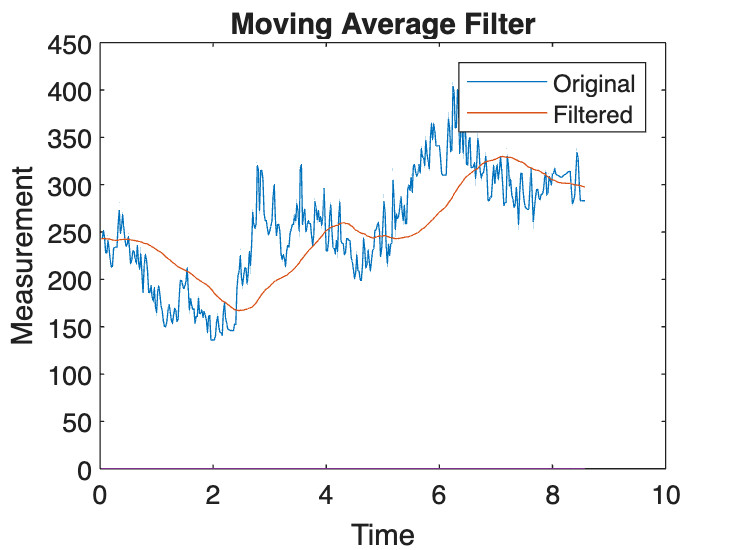

file = readmatrix("/Users/valeriynovytskyy/Desktop/kalman/input.csv");
time = file(:,1);
input = file(:,2);
size = 82;

output = movingAverageFilter(input, size);

plot(time, input, time, output);
title('Moving Average Filter');
xlabel("Time");
ylabel("Measurement");
legend("Original", "Filtered");

## Low Pass

A basic low pass filter looks like this:

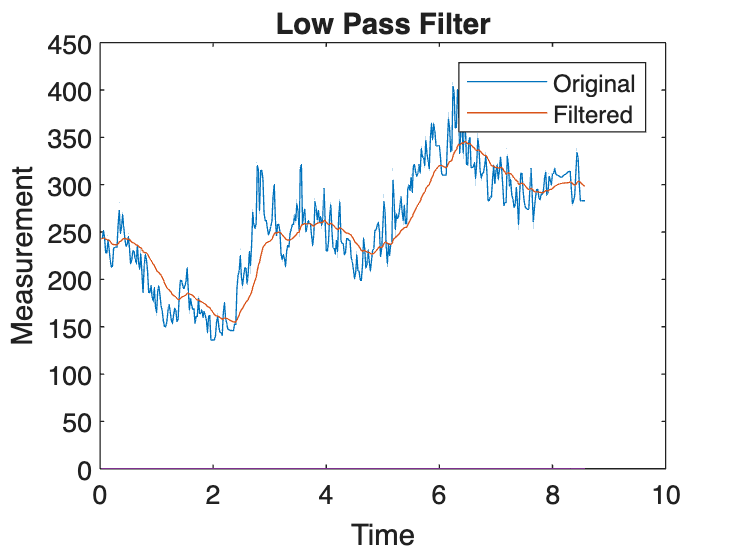

file2 = readmatrix("/Users/valeriynovytskyy/Desktop/kalman/input.csv");
time = file2(:,1);
input = file2(:,2);
coefficient = 0.0572;

output = lowPassFilter(input, coefficient);

plot(time, input, time, output);
title('Low Pass Filter');
xlabel("Time");
ylabel("Measurement");
legend("Original", "Filtered");

## Explore Other Types of Smoothing

The Smooth Data functionality in Matlab is great for pre-processing data before generating a model.

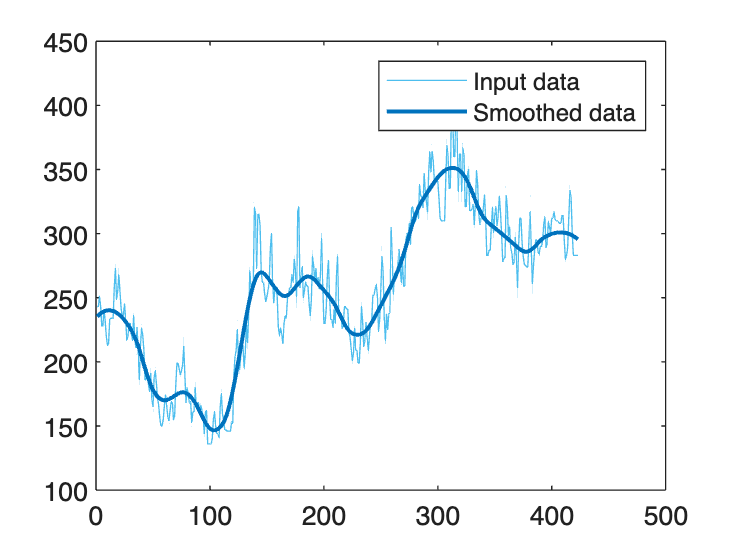

% Smooth input data
smoothedData = smoothdata(reading,"loess","SmoothingFactor",0.25);

% Display results
figure
plot(reading,"SeriesIndex",6,"DisplayName","Input data")
hold on
plot(smoothedData,"SeriesIndex",1,"LineWidth",1.5,"DisplayName","Smoothed data")
hold off
legend

### Low Pass Filter Implementation

function output = lowPassFilter(input, coefficient)
  estimate = input(1);
  output = zeros(length(input));

  for sampleIndex = 1:length(input)
    estimate = (1.0 - coefficient) * estimate + ...
      coefficient * input(sampleIndex);

    output(sampleIndex) = estimate;
  end
end

### Moving Average Filter Implementation

function output = movingAverageFilter(input, size)
  buffer = ones(size, 1) * input(1);
  output = zeros(length(input));

  for sampleIndex = 1:length(input)
    bufferIndex = mod(sampleIndex - 1, size) + 1;
    buffer(bufferIndex) = input(sampleIndex);
    output(sampleIndex) = sum(buffer) / size;
  end
end
